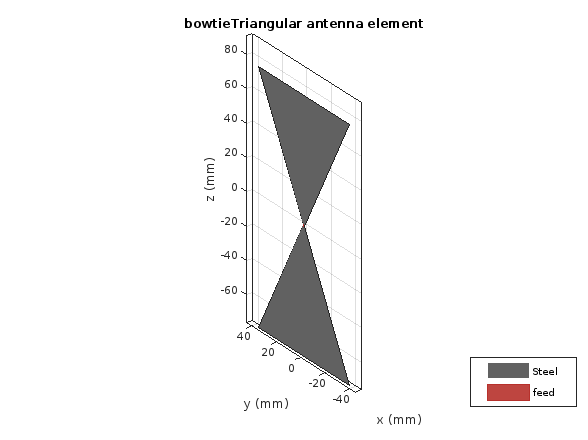

% Designing a planar bowtie antenna
f = 455e6;
m = metal('Steel');
b = bowtieTriangular('Length',0.152, 'FlareAngle', 2*atan(0.0511/0.1046)*180/pi, 'Conductor', m);
show(b)

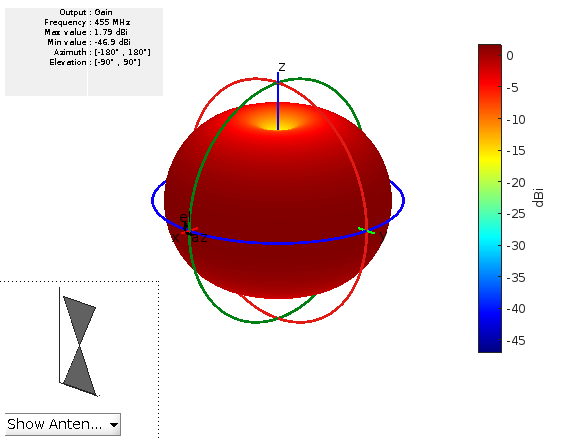

% Radiation Pattern
pattern(b,f);

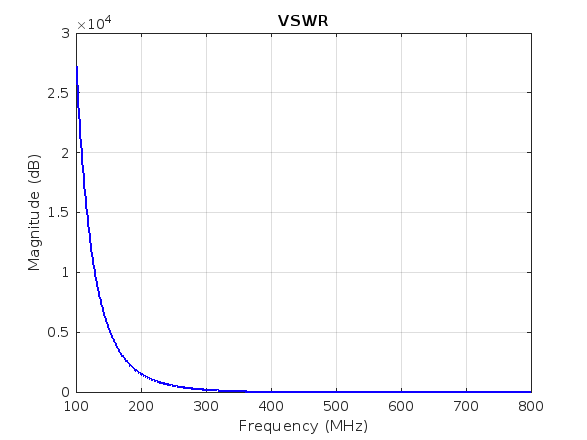

% VSWR
vswr(b,100e6:1e6:800e6)

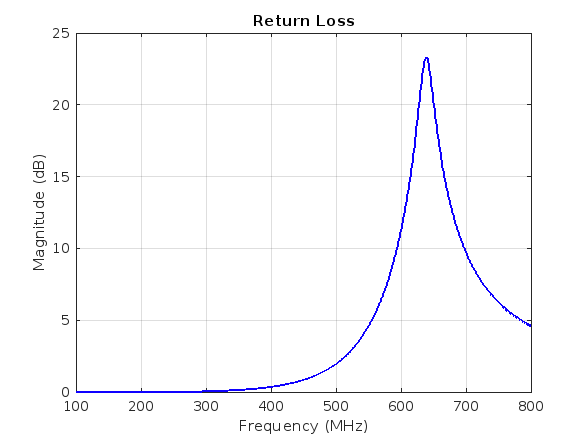

% Return Loss
returnLoss(b, 100e6:1e6:800e6)

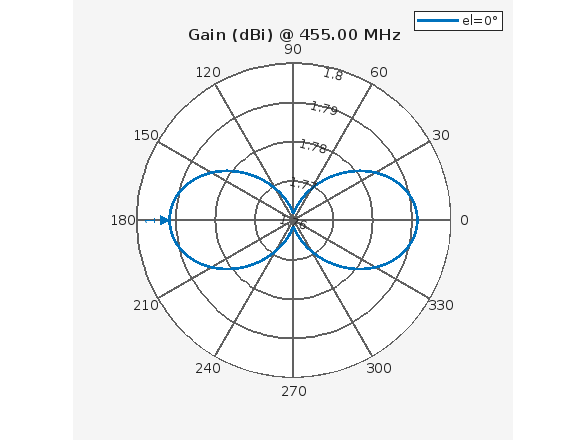

% Azimuth Plane Pattern ( Side View )
patternAzimuth(b, f)

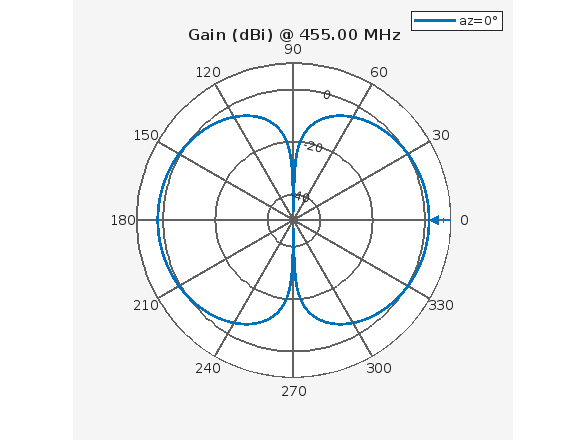

% Elevation Plane Pattern ( Front View )
patternElevation(b, f)

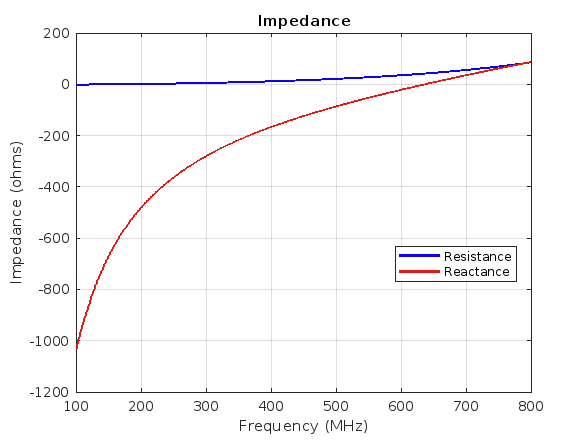

% impedance
impedance (b,100e6:1e6:800e6)

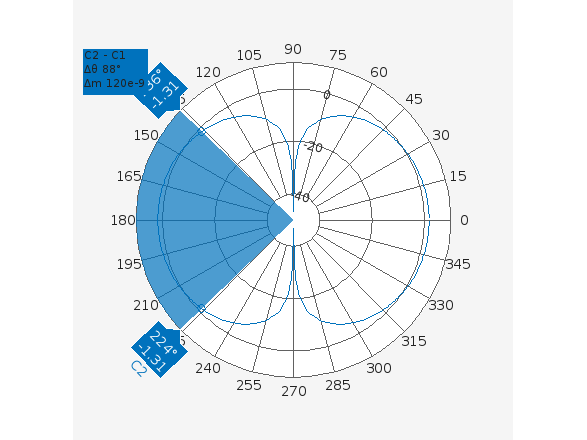

% HPBW for azimuth angle = 0
beamwidth(b,f, 0, 1:1:360, 3);

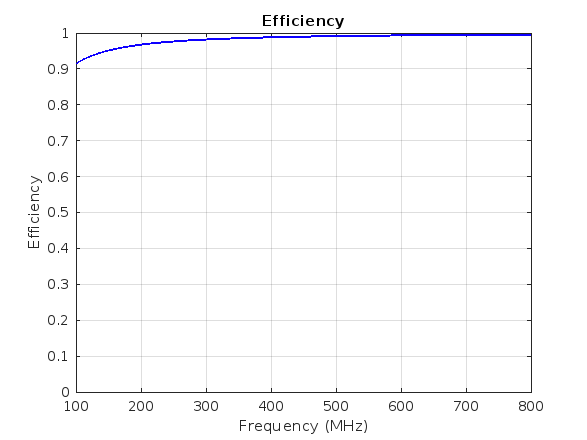

% Efficiency
efficiency(b,100e6:1e6:800e6)

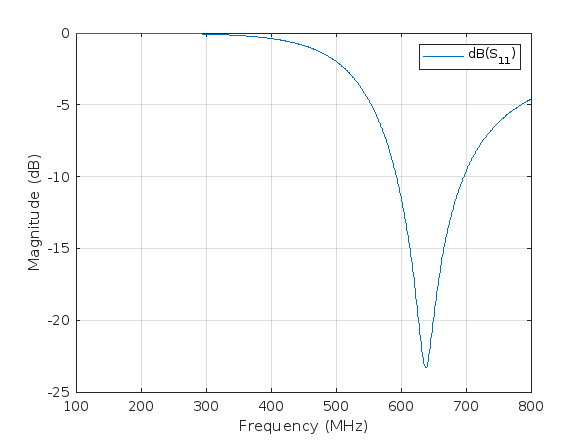

% s-parameters
sobj = sparameters(b,100e6:1e6:800e6);
rfplot(sobj)